# Airy disk visualization

All lengths are in [m].

clear
E0 = 1;
lam = 500e-9;
diaLens = 25e-3;
fLens = 50e-3;

k = 2*pi/lam;
NA = diaLens/2/fLens

NA = 0.2500

2D grid of (x,y)

dx = 0.1e-6;  % 0.1 um
x = -5e-6:dx:5e-6;  y = -5e-6:dx:5e-6;  
x = x+dx/2;  y = y+dx/2;  % to avoid dividing by zero
nx = length(x);  ny = length(y);

[gx,gy] = ndgrid(x,y);
size(gx)

ans =    101   101


Intensity pattern

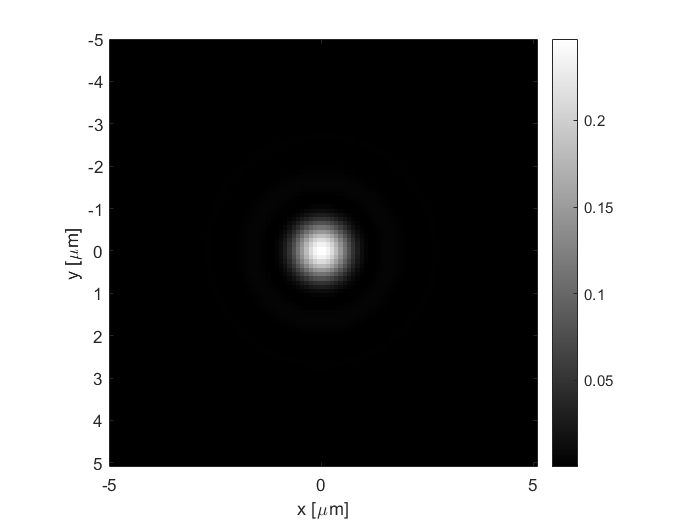

rho = sqrt(gx.^2+gy.^2);
inten = E0^2 * besselj(1,k*NA*rho).^2 ./ (k*NA*rho).^2;

figure;  colormap(gray);
imagesc(x*1e6,y*1e6,inten')
set(gca,'xdir','normal')
axis image
colorbar
xlabel('x [\mum]')
ylabel('y [\mum]')

Adjust the presentation range

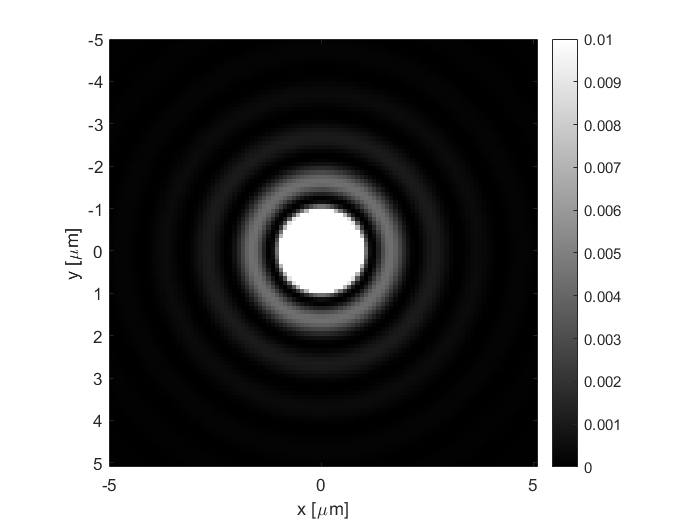

figure;  colormap(gray);
imagesc(x*1e6,y*1e6,inten')
set(gca,'xdir','normal')
axis image
colorbar
set(gca,'clim',[0 0.01])
xlabel('x [\mum]')
ylabel('y [\mum]')

Plot the intensity as a function of $\rho$

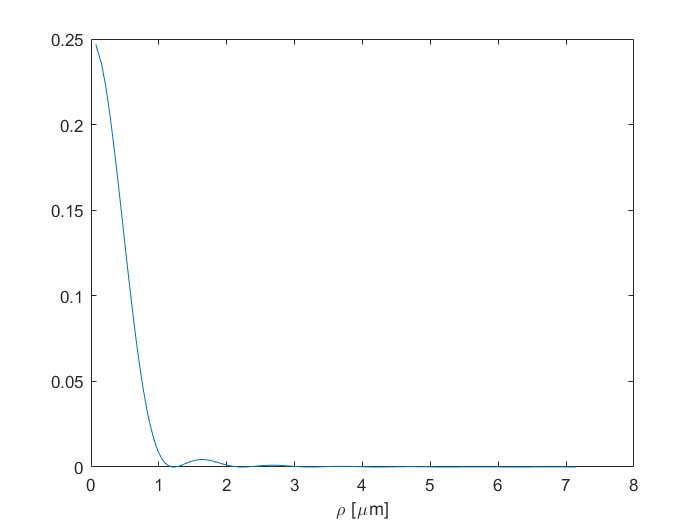

[rhoSorted,is] = sort(rho(:));
intenSorted = inten(:);  
intenSorted = inten(is);

figure
plot(rhoSorted*1e6,intenSorted)
xlabel('\rho [\mum]')

Find $\rho$ of the first zero

iRho = find(intenSorted==0)


iRho =

  0×1 empty double column vector




[~,iRho1] = min(abs(rhoSorted-1e-6))

iRho1 = 313

[~,iRho2] = min(abs(rhoSorted-2e-6))

iRho2 = 1265


[m,iRho] = min(intenSorted(iRho1:iRho2))

m = 9.6437e-06

iRho = 149

iRho = iRho + iRho1-1

iRho = 461

rhoSorted(iRho)

ans = 1.2104e-06

diaAiry = rhoSorted(iRho)*2

diaAiry = 2.4207e-06

Theoretical value

diaAiryTheory = 1.22*lam/NA

diaAiryTheory = 2.4400e-06